Purpose: help to design a multi-dose experiment that effectively uses the concentrations available for gaining maximum information for synergy or efficacy applications.

Why use log2? This gives us the ability to estimate Bliss and 

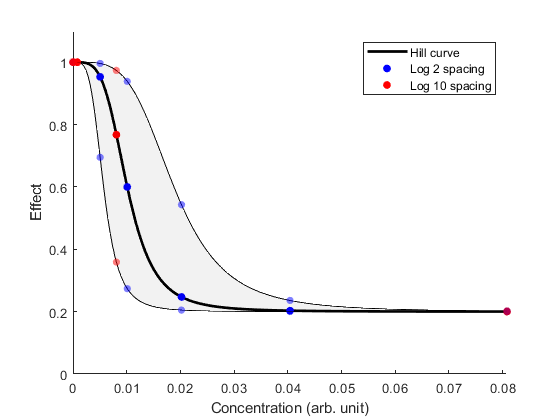

% drug properties
E0 = 1;
Emax = 0.2;
EC50 = 0.0101;
hill_coeff = 4;

drug1 = struct;
drug1.E0 = E0;
drug1.Emax = Emax;
drug1.C = EC50;
drug1.h = hill_coeff;

C_upper_bound = 0.0188;
C_lower_bound = 0.0057;
drug2 = drug1;
drug2.C = C_upper_bound;
drug3 = drug1;
drug3.C = C_lower_bound;

% how to define max dose
dose_mode = "multiple_EC50";
if dose_mode == "concentration"
    max_dose = 1000;
elseif dose_mode =="multiple_EC50"
    max_dose = drug1.C *8;
end

d = linspace(0, max_dose, 200);
E = hill(d, drug1);

% number of concentration points not including control (i.e. 0)
nPoints = 5;
log_spacing = linspace(-(nPoints-1), 0, nPoints);
points_log2 = [0, 2.^(log_spacing + log2(max_dose))];
points_log10 = [0, 10.^(log_spacing + log10(max_dose))];

% figure 1: linear scale
figure(1); clf
hold on
plot(d, E, 'k-', 'linewidth', 2)
plot(points_log2, hill(points_log2, drug1), '.b', 'markersize', 20)
plot(points_log10, hill(points_log10, drug1), '.r', 'markersize', 20)
plot(d, hill(d, drug2), '-', 'color', [.2, .2, .2])
plot(d, hill(d, drug3), '-', 'color', [.2, .2, .2])
inBetween = [hill(d, drug2), fliplr(hill(d, drug3))];
fill([d, fliplr(d)], inBetween, 'k', 'facealpha', 0.05);
xlabel('Concentration (arb. unit)')
ylabel('Effect')

scatter(points_log2, hill(points_log2, drug2), 30, 'b', 'filled', 'markerfacealpha', 0.5)
scatter(points_log10, hill(points_log10, drug2), 30, 'r', 'filled', 'markerfacealpha', 0.5)
scatter(points_log2, hill(points_log2, drug3), 30, 'b', 'filled', 'markerfacealpha', 0.5)
scatter(points_log10, hill(points_log10, drug3), 30, 'r', 'filled', 'markerfacealpha', 0.5)

legend({'Hill curve', 'Log 2 spacing', 'Log 10 spacing'}, 'location', 'northeast')
%legend({'Hill curve', 'Log 2 spacing'}, 'location', 'northeast')
axis([0 max_dose 0 1.1])
hold off

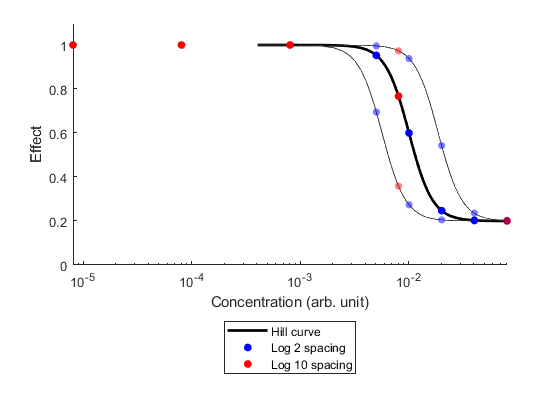


% figure 2: log scale
figure(2); clf
hold on
plot(d, E, 'k-', 'linewidth', 2)
plot(points_log2, hill(points_log2, drug1), '.b', 'markersize', 20)
plot(points_log10, hill(points_log10, drug1), '.r', 'markersize', 20)
plot(d, hill(d, drug2), '-', 'color', [.2, .2, .2])
plot(d, hill(d, drug3), '-', 'color', [.2, .2, .2])
xlabel('Concentration (arb. unit)')
ylabel('Effect')
axis([0 max_dose 0 1.1])

scatter(points_log2, hill(points_log2, drug2), 30, 'b', 'filled', 'markerfacealpha', 0.5)
scatter(points_log10, hill(points_log10, drug2), 30, 'r', 'filled', 'markerfacealpha', 0.5)
scatter(points_log2, hill(points_log2, drug3), 30, 'b', 'filled', 'markerfacealpha', 0.5)
scatter(points_log10, hill(points_log10, drug3), 30, 'r', 'filled', 'markerfacealpha', 0.5)

set(gca, 'xscale', 'log')
axis([0 max_dose 0 1.1])
legend({'Hill curve', 'Log 2 spacing', 'Log 10 spacing'}, 'location', 'southoutside')
hold off

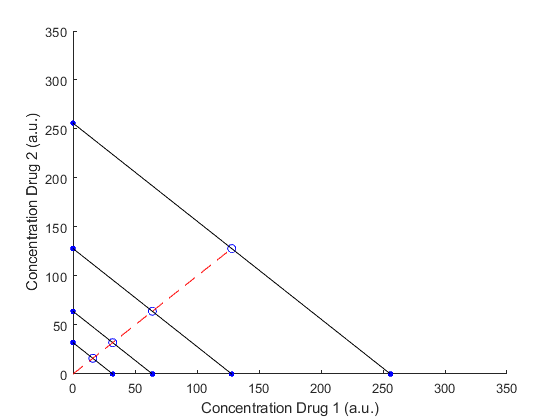

% figure 3: 2D plot test
figure; hold on

n = 5;
for i = 1:4
    plot(2^n, 0, '.b', 'MarkerSize', 10)
    plot(0, 2^n, '.b', 'MarkerSize', 10)
    plot(2^(n-1), 2^(n-1), 'ob')
    plot([0, 2^n], [2^n, 0], '-k')
    
    % iterate power
    n = n+1;
end
hold off

hold on
plot([0, 2^7], [0, 2^7], '--r')

%set(gca, 'xscale', 'log')
%set(gca, 'yscale', 'log')
hold off
axis([0 350 0 350])
xlabel('Concentration Drug 1 (a.u.)')
ylabel('Concentration Drug 2 (a.u.)')

function E = hill(d, params)
    E0 = params.E0;
    Emax = params.Emax;
    C = params.C;
    h = params.h;
    
    E = E0 + (Emax - E0) .* (d.^h ./ (C.^h + d.^h));
end